# Integrity of hybrid Galileo + 5G EKF

Reproducible MATLAB Live Script. Based on A6_ekf.m and Section 3.2.5 of the master thesis, 5G Assisted Precise Positioning in GNSS (2026). New research contribution: propagation of estimation uncertainty, nominal protection levels, NIS monitoring, NEES diagnostics, deterministic measurement bias bounds and controlled fault injection.

WARNING: HPL and VPL are single-epoch, fault-free Gaussian bounds unless explicit bounded-bias assumptions hold. This is NOT a certified RAIM/ARAIM integrity algorithm. Full integrity requires fault hypotheses, allocated missed-detection probabilities and conservative error models.

State: x = [East, North, Up, vEast, vNorth, vUp, receiver clock bias in metres]. P is the 7 by 7 state-error covariance. All geometric observables are processed in metres.

## 1. Configuration and required input data

The project must contain config.m, the utils directory and the MAT files referenced by rxENUFile, galLoSFile, nrObsFile, nrSimFile, nrLoSFile. Required variables: receiverPositions, samplingRate; measPseudorange, Fs_gnss, svPositions_ENU; tdoaEstim; Ts5g_pos; LoSbStationsENU, LoSMatrix.

TDOA observables are assumed to represent TOA(other) minus TOA(reference), in seconds. Optional tdoaReferenceIndex (one 1-based global BS index per 5G epoch) should be stored in nrObsFile. If absent, the first visible BS is assumed; this assumption MUST be checked against the data-generation code.

Example HAL and VAL below are only research thresholds; replace them with application requirements. Per-epoch risk is not the probability over the whole trajectory.

addpath('./utils','./config');
assert(exist('config','file') == 2, 'config.m was not found in the MATLAB path.');
run('config');

settings = struct();
settings.sigmaGNSS_m       = 10;       % Standard deviation of ONE pseudorange [m]
settings.sigmaTDOA_m       = 5;        % Std of ONE range-difference measurement [m]
settings.tdoaUnits        = 'seconds'; % 'seconds', 'nanoseconds', or 'metres'
settings.tdoaSign         = 1;         % +1: TOA(other)-TOA(ref); -1: reverse
settings.gnssFirstEpoch_s = 0;         % Adjust if measurements start at dtGNSS
settings.nrFirstEpoch_s   = 0;         % Adjust if measurements start at dt5G
settings.correlatedTDOA   = true;      % Accounts for shared reference TOA
settings.Qmode            = 'legacy';  % 'legacy' or 'continuous_acceleration'
settings.qAccel           = 2;         % [m^2/s^3], only for continuous_acceleration
settings.qClock           = 2;         % [m^2/s], only for continuous_acceleration
settings.pHMI_per_epoch   = 1e-5;      % Nominal total per-epoch tail allocation
settings.pFalseAlarm      = 1e-3;      % NIS threshold per sensor-update event
settings.gateMeasurements = true;      % Reject block if NIS exceeds its threshold
settings.maxGNSSBias_m    = 0;         % Hard bound PER GNSS observation, not variance
settings.maxTDOABias_m    = 0;         % Hard bound PER 5G range-difference observation
settings.HAL_m            = 30;        % Illustrative Horizontal Alert Limit [m]
settings.VAL_m            = 50;        % Illustrative Vertical Alert Limit [m]
settings.burnInEpochs     = 4;         % Discard initialization epochs in diagnostics
settings.initialPositionFromTruth = true; % ONLY legitimate in simulation

% Controlled fault injection (disabled by default).
fault = struct('enabled',false,'source','GNSS', ...
    'start_s',0.030,'end_s',0.080,'index',1,'bias_m',100);

assert(settings.pHMI_per_epoch > 0 && settings.pHMI_per_epoch < 1);
assert(settings.pFalseAlarm > 0 && settings.pFalseAlarm < 1);
assert(settings.sigmaGNSS_m > 0 && settings.sigmaTDOA_m > 0);
assert(settings.maxGNSSBias_m >= 0 && settings.maxTDOABias_m >= 0);
assert(settings.HAL_m > 0 && settings.VAL_m > 0);

rx = load(rxENUFile,'receiverPositions','samplingRate');
ga = load(galLoSFile,'measPseudorange','Fs_gnss','svPositions_ENU');
nr = load(nrObsFile); % tdoaEstim; optional tdoaReferenceIndex
ns = load(nrSimFile,'Ts5g_pos');
lo = load(nrLoSFile,'LoSbStationsENU','LoSMatrix');

receiverPositions = rx.receiverPositions;
measPseudorange   = ga.measPseudorange;
svPositions_ENU   = ga.svPositions_ENU;
tdoaEstim         = nr.tdoaEstim;
LoSbStationsENU   = lo.LoSbStationsENU;
LoSMatrix         = lo.LoSMatrix;

N = size(receiverPositions,1);
Ng = size(measPseudorange,2);
Nbs = size(LoSbStationsENU,1);
assert(size(receiverPositions,2)==3 && size(LoSbStationsENU,2)==3);
assert(size(svPositions_ENU,1)==size(measPseudorange,1));
assert(size(svPositions_ENU,2)==3 && size(svPositions_ENU,3)==Ng);
assert(size(tdoaEstim,2)==Nbs, ...
    'Expected tdoaEstim as [N5G x NbaseStations] in GLOBAL BS column order.');
assert(size(LoSMatrix,2)==Nbs, 'LoSMatrix BS columns do not match.');
assert(all(isfinite(receiverPositions(:))), 'Truth trajectory contains invalid data.');

dt=1/rx.samplingRate;
dtGNSS=1/ga.Fs_gnss;
dt5G=ns.Ts5g_pos;
assert(dt>0 && dtGNSS>0 && dt5G>0);
N5G=size(tdoaEstim,1);
t=(0:N-1)*dt;

fprintf('Loaded %d receiver epochs, %d GNSS epochs and %d 5G epochs.\n',N,Ng,N5G);

Loaded 367 receiver epochs, 184 GNSS epochs and 183 5G epochs.


if isfield(nr,'tdoaReferenceIndex')
    tdoaReferenceIndex=nr.tdoaReferenceIndex(:);
    assert(numel(tdoaReferenceIndex)==N5G, 'tdoaReferenceIndex length mismatch.');
    referenceVerified=true;
else
    tdoaReferenceIndex=nan(N5G,1);
    referenceVerified=false;
    warning(['No tdoaReferenceIndex found. Assuming first visible BS is the ', ...
             'reference. Verify against the TDOA generator before interpreting results.']);
end

## 2. Synchronization and modelling tests

Time origin is t(k)=(k-1)/samplingRate. With zero measurement-time offsets, 367 high-rate epochs and 184 GNSS epochs map as 1,3,...,367 when sampling rates differ by a factor of two. If the first measurement is generated at dtGNSS or dt5G, set gnssFirstEpoch_s / nrFirstEpoch_s accordingly. No equality comparison of floating-point time stamps is used.

The 5G Jacobian is the derivative of range difference in metres: H(j,1:3) = (p-s_j)/||p-s_j|| - (p-s_r)/||p-s_r||. A finite-difference test protects against sign/unit mistakes.


$$\mathbf P_k^-=\mathbf F_k\mathbf P_{k-1}^+\mathbf F_k^T+\mathbf Q_k$$



$$\mathbf H_{j,r}=\left[\frac{\mathbf p-\mathbf s_j}{\|\mathbf p-\mathbf s_j\|}-\frac{\mathbf p-\mathbf s_r}{\|\mathbf p-\mathbf s_r\|} \quad \mathbf 0_{1\times3} \quad 0\right]$$


gnssAtRx=zeros(1,N);
gnssRxIndices=1+round((settings.gnssFirstEpoch_s+(0:Ng-1)*dtGNSS)/dt);
validGNSS = gnssRxIndices>=1 & gnssRxIndices<=N;
assert(numel(unique(gnssRxIndices(validGNSS)))==nnz(validGNSS), ...
       'Two GNSS epochs map onto the same filter sample.');
for g=find(validGNSS)
    gnssAtRx(gnssRxIndices(g))=g;
end

nrAtRx=zeros(1,N);
nrRxIndices=1+round((settings.nrFirstEpoch_s+(0:N5G-1)*dt5G)/dt);
validNR = nrRxIndices>=1 & nrRxIndices<=N;
assert(numel(unique(nrRxIndices(validNR)))==nnz(validNR), ...
       'Two 5G epochs map onto the same filter sample. Increase filter rate.');
for j=find(validNR)
    nrAtRx(nrRxIndices(j))=j;
end

assert(nnz(gnssAtRx)>0 && nnz(nrAtRx)>0, ...
       'No mapped GNSS or 5G epochs fall inside the receiver timeline.');

% Finite-difference test: geometry and Jacobian must share the same sign.
pTest=[4;5;6];
sRef=[0;0;0];
sOther=[10;0;0];
unitOther=(pTest-sOther)/norm(pTest-sOther);
unitRef=(pTest-sRef)/norm(pTest-sRef);
J=unitOther-unitRef;
h=@(p) norm(p-sOther)-norm(p-sRef);
step=1e-4;
for j=1:3
    delta=zeros(3,1); delta(j)=step;
    Jnumeric=(h(pTest+delta)-h(pTest-delta))/(2*step);
    assert(abs(Jnumeric-J(j))<1e-7, 'TDOA Jacobian test failed.');
end

disp('Time mapping and analytical TDOA Jacobian tests: OK');

Time mapping and analytical TDOA Jacobian tests: OK


## 3. EKF and integrity mathematics

Prediction: 


$$x^{-} = F x^{+}_{previous}$$



$$P^{-} = F P^{+}_{previous} F^T + Q$$
 

Posterior: 

K=P_minus H^T (H P_minus H^T+R)^(-1), 

x_plus=x_minus+K(z-h), 

P_plus=(I-KH)P_minus(I-KH)^T+KRK^T (Joseph stabilized covariance).

Under the nominal unbiased Gaussian hypothesis, $P_{EN}$ is the top-left 2x2 block of the ENU position covariance. A conservative horizontal radial bound is HPL0 = sqrt(-2 ln(pH)) sqrt(lambda_max(P_EN)); the vertical two-sided bound is VPL0 = sqrt(2) erfcinv(pV) sqrt(P_UU). Here pH=pV=pHMI_per_epoch/2.

For shared-reference TDOA and independent equal-variance TOA errors: Cov(d_j,d_l)=sigma_TOA^2*(delta_jl+1). sigmaTDOA_m is the std of a DIFFERENCE, hence R5G=(sigmaTDOA_m^2/2)*(I+ones). This model is conditional on independent TOA errors. Sensor/epoch timestamps must be verified before interpreting PLs.

Optional interval propagation for all bounded measurement biases: B_minus=abs(F)*B_previous, B_plus=abs(I-KH)*B_minus+abs(K)*(biasBound*ones). HPL=HPL0+norm(B_E,B_N); VPL=VPL0+B_U. This is a linearized upper bound on deterministic measurement bias effects, NOT a bound for arbitrary unmodelled faults or model errors.


$$\mathrm{HPL}_{0,k}=\sqrt{-2\ln(p_H)}\sqrt{\lambda_{\max}(\mathbf P_{EN,k})}$$



$$\mathrm{VPL}_{0,k}=\sqrt{2}\mathrm{erfc}^{-1}(p_V)\sqrt{P_{UU,k}}$$



$$\mathbf P_k^+=(\mathbf I-\mathbf K_k\mathbf H_k)\mathbf P_k^-(\mathbf I-\mathbf K_k\mathbf H_k)^T+\mathbf K_k\mathbf R_k\mathbf K_k^T$$


I7=eye(7);
F=[eye(3),dt*eye(3),zeros(3,1); ...
   zeros(3),eye(3),zeros(3,1); ...
   zeros(1,6),1];
if strcmp(settings.Qmode,'legacy')
    Q=blkdiag(1e-2*eye(3),1e-1*eye(3),10);
elseif strcmp(settings.Qmode,'continuous_acceleration')
    % Integrated continuous white-acceleration and clock random walks.
    Q=zeros(7);
    Q(1:3,1:3)=settings.qAccel*(dt^3/3)*eye(3);
    Q(1:3,4:6)=settings.qAccel*(dt^2/2)*eye(3);
    Q(4:6,1:3)=Q(1:3,4:6)';
    Q(4:6,4:6)=settings.qAccel*dt*eye(3);
    Q(7,7)=settings.qClock*dt;
else
    error('Unknown Qmode.');
end

x=zeros(7,1);
if settings.initialPositionFromTruth
    x(1:3)=receiverPositions(1,:)';
    warning('Initial position comes from ground truth: simulation-only initialization.');
else
    error('Set an externally computed initialPositionENU before enabling operational use.');
end

P=diag([1e6*ones(3,1);100*ones(3,1);1e4]);
B=zeros(7,1); % Initial deterministic bias bound. Does NOT cover initial-state error.

% Two disjoint allocations of the nominal per-epoch Gaussian tail budget.
pH=settings.pHMI_per_epoch/2;
pV=settings.pHMI_per_epoch/2;
kH=sqrt(-2*log(pH));
kV=sqrt(2)*erfcinv(pV);

% Allocate filter outputs and diagnostics.
x_est=nan(7,N);
Ppos=nan(3,3,N);
PposPrior=nan(3,3,N);
HPL0=nan(1,N); VPL0=nan(1,N);
HPL=nan(1,N); VPL=nan(1,N);
BiasHoriz=nan(1,N); BiasVert=nan(1,N);
NISgnss=nan(1,N); NIS5g=nan(1,N);
NISThreshGnss=nan(1,N); NISThresh5g=nan(1,N);
NEESpos=nan(1,N);
numberGNSS=zeros(1,N); numberTDOA=zeros(1,N);
GNSSaccepted=false(1,N); NRaccepted=false(1,N);
GNSSalarm=false(1,N); NRalarm=false(1,N);

% Measurement covariance options are established at every sensor update.
RgnssVariance=settings.sigmaGNSS_m^2;
RtdoaVariance=settings.sigmaTDOA_m^2;

## 4. Sequential Galileo + 5G EKF and integrity monitoring

Each sensor block uses an independent innovation whitened by its predicted S. NIS=y^T S^(-1) y is compared with the chi-square quantile 2*gammaincinv(1-Pfa,m/2). A failed event triggers an alarm; when gating is enabled its measurements are excluded.

The filter accepts even a single GNSS observable or a single valid TDOA difference; the prior constrains a partial observation. Four transmitters are needed for a standalone instantaneous 3D TDOA fix, but not for a sequential EKF update.


$$\mathrm{NIS}_k=\mathbf y_k^T\mathbf S_k^{-1}\mathbf y_k \sim \chi_m^2\quad (H_0)$$


for k=1:N
    if k>1
        x=F*x;
        P=F*P*F'+Q;
        P=(P+P')/2;
        B=abs(F)*B;
    end
    PposPrior(:,:,k)=P(1:3,1:3);

    % ------------------------ GALILEO UPDATE ------------------------
    g=gnssAtRx(k);
    if g>0
        satIdx=find(isfinite(measPseudorange(:,g)) & ...
                    all(isfinite(svPositions_ENU(:,:,g)),2));
        m=numel(satIdx);
        numberGNSS(k)=m;
        if m>0
            sv=squeeze(svPositions_ENU(satIdx,:,g));
            sv=reshape(sv,m,3);
            z=measPseudorange(satIdx,g);
            z=z(:);
            if fault.enabled && strcmpi(fault.source,'GNSS') && ...
                    t(k)>=fault.start_s && t(k)<=fault.end_s
                loc=find(satIdx==fault.index,1);
                if ~isempty(loc), z(loc)=z(loc)+fault.bias_m; end
            end
            dp=x(1:3)'-sv;
            r=sqrt(sum(dp.^2,2));
            if any(r<=0), error('Degenerate GNSS geometry at epoch %d.',k); end
            h=r+x(7); % Clock bias in metres (consistent with A6_ekf.m)
            H=zeros(m,7);
            H(:,1:3)=dp./r;
            H(:,7)=1;
            R=RgnssVariance*eye(m);
            y=z-h;
            S=H*P*H'+R;
            S=(S+S')/2;
            [~,pdFlag]=chol(S);
            if pdFlag~=0, error('GNSS innovation covariance not positive definite.'); end
            NISgnss(k)=real(y'*(S\y));
            NISThreshGnss(k)=2*gammaincinv(1-settings.pFalseAlarm,m/2);
            GNSSalarm(k)=NISgnss(k)>NISThreshGnss(k);
            if ~(settings.gateMeasurements && GNSSalarm(k))
                K=(P*H')/S;
                A=I7-K*H;
                x=x+K*y;
                P=A*P*A'+K*R*K';
                P=(P+P')/2;
                B=abs(A)*B+abs(K)*(settings.maxGNSSBias_m*ones(m,1));
                GNSSaccepted(k)=true;
            end
        end
    end

    % -------------------------- 5G UPDATE --------------------------
    j=nrAtRx(k);
    if j>0
        if size(LoSMatrix,1)==N
            losRow=LoSMatrix(k,:);
        elseif size(LoSMatrix,1)==N5G
            losRow=LoSMatrix(j,:);
        else
            error(['LoSMatrix must contain N receiver rows or N5G rows. ', ...
                   'Check LOS sampling and timestamps.']);
        end
        visible=isfinite(losRow) & losRow~=0 & all(isfinite(LoSbStationsENU),2)';
        vBS=find(visible);
        if ~isempty(vBS)
            if referenceVerified
                ref=tdoaReferenceIndex(j);
            else
                ref=vBS(1); % ASSUMPTION: verify actual TDOA data convention.
            end
            if isfinite(ref) && ref==floor(ref) && ref>=1 && ref<=Nbs && visible(ref)
                other=vBS(vBS~=ref & isfinite(tdoaEstim(j,vBS)));
                m=numel(other);
                numberTDOA(k)=m;
                if m>0
                    z=tdoaEstim(j,other)';
                    switch lower(settings.tdoaUnits)
                        case 'seconds'
                            z=z*299792458;
                        case 'nanoseconds'
                            z=z*1e-9*299792458;
                        case 'metres'
                            % Already expressed as range difference [m].
                        otherwise
                            error('Unknown TDOA units.');
                    end
                    z=settings.tdoaSign*z;
                    if fault.enabled && strcmpi(fault.source,'5G') && ...
                            t(k)>=fault.start_s && t(k)<=fault.end_s
                        loc=find(other==fault.index,1);
                        if ~isempty(loc), z(loc)=z(loc)+fault.bias_m; end
                    end
                    bsOther=LoSbStationsENU(other,:);
                    bsRef=LoSbStationsENU(ref,:);
                    dOther=x(1:3)'-bsOther;
                    dRef=x(1:3)'-bsRef;
                    rother=sqrt(sum(dOther.^2,2));
                    rref=norm(dRef);
                    if any(rother<=0)||rref<=0
                        error('Degenerate 5G geometry at epoch %d.',k);
                    end
                    h=rother-rref;
                    H=zeros(m,7);
                    H(:,1:3)=dOther./rother-dRef/rref;
                    if settings.correlatedTDOA
                        % sigmaTDOA_m denotes the std of an individual DIFFERENCE.
                        R=(RtdoaVariance/2)*(eye(m)+ones(m));
                    else
                        R=RtdoaVariance*eye(m);
                    end
                    y=z-h;
                    S=H*P*H'+R;
                    S=(S+S')/2;
                    [~,pdFlag]=chol(S);
                    if pdFlag~=0, error('5G innovation covariance not positive definite.'); end
                    NIS5g(k)=real(y'*(S\y));
                    NISThresh5g(k)=2*gammaincinv(1-settings.pFalseAlarm,m/2);
                    NRalarm(k)=NIS5g(k)>NISThresh5g(k);
                    if ~(settings.gateMeasurements && NRalarm(k))
                        K=(P*H')/S;
                        A=I7-K*H;
                        x=x+K*y;
                        P=A*P*A'+K*R*K';
                        P=(P+P')/2;
                        B=abs(A)*B+abs(K)*(settings.maxTDOABias_m*ones(m,1));
                        NRaccepted(k)=true;
                    end
                end
            end
        end
    end

    % ----------- NOMINAL PROTECTION LEVELS / BIAS BOUNDS -----------
    x_est(:,k)=x;
    Ppos(:,:,k)=P(1:3,1:3);
    PEN=(P(1:2,1:2)+P(1:2,1:2)')/2;
    HPL0(k)=kH*sqrt(max(max(eig(PEN)),0));
    VPL0(k)=kV*sqrt(max(P(3,3),0));
    BiasHoriz(k)=norm(B(1:2));
    BiasVert(k)=B(3);
    HPL(k)=HPL0(k)+BiasHoriz(k);
    VPL(k)=VPL0(k)+BiasVert(k);

    % NEES uses truth only for OFFLINE validation; never for filtering.
    err=x(1:3)-receiverPositions(k,:)';
    P3=P(1:3,1:3);
    if all(isfinite(P3(:))) && all(isfinite(err))
        [~,pdFlag]=chol(P3);
        if pdFlag==0
            NEESpos(k)=real(err'*(P3\err));
        end
    end
end

disp('Asynchronous hybrid EKF and integrity analysis completed.');

Asynchronous hybrid EKF and integrity analysis completed.


## 5. Error containment, alarms and empirical validation

The horizontal error is sqrt((Eest-Etruth)^2+(Nest-Ntruth)^2); the vertical error is abs(Uest-Utruth). Coverage is calculated only after burn-in. NIS checks measurement consistency, NEES checks the position covariance against ground truth. One trajectory cannot establish rare-event integrity risk.

An alert is raised when a NIS threshold is exceeded; an estimate is available only if both calculated bounds are within the selected HAL and VAL and no contemporaneous NIS alert is present. Fault rejection is not proof of missed-detection probability.

errorENU=x_est(1:3,:)-receiverPositions';
horizontalError=hypot(errorENU(1,:),errorENU(2,:));
verticalError=abs(errorENU(3,:));
positionError=sqrt(sum(errorENU.^2,1));

sampleUsed=false(1,N);
assert(settings.burnInEpochs < N, 'burnInEpochs must be smaller than N.');
sampleUsed(settings.burnInEpochs+1:end)=true;
anyAlarm=GNSSalarm|NRalarm;
withinPL_H=horizontalError<=HPL;
withinPL_V=verticalError<=VPL;
available=(HPL<=settings.HAL_m)&(VPL<=settings.VAL_m)&~anyAlarm;
% Observed HMI on the ONE simulated trajectory. Not a probability estimate.
observedHMI_H=sampleUsed&available&(horizontalError>settings.HAL_m);
observedHMI_V=sampleUsed&available&(verticalError>settings.VAL_m);

summary=struct();
summary.N=N;
summary.GNSSaccepted=sum(GNSSaccepted);
summary.NRaccepted=sum(NRaccepted);
summary.GNSSalarms=sum(GNSSalarm);
summary.NRalarms=sum(NRalarm);
summary.RMS_horizontal_m=sqrt(mean(horizontalError(sampleUsed).^2));
summary.RMS_vertical_m=sqrt(mean(verticalError(sampleUsed).^2));
summary.nominalHorizontalContainment=mean(horizontalError(sampleUsed)<=HPL0(sampleUsed));
summary.nominalVerticalContainment=mean(verticalError(sampleUsed)<=VPL0(sampleUsed));
summary.boundedHorizontalContainment=mean(withinPL_H(sampleUsed));
summary.boundedVerticalContainment=mean(withinPL_V(sampleUsed));
summary.availabilityFraction=mean(available(sampleUsed));
summary.observedHMI_H=sum(observedHMI_H);
summary.observedHMI_V=sum(observedHMI_V);
summary.meanNEESpos=mean(NEESpos(sampleUsed),'omitnan');
summary.referenceIndexSupplied=referenceVerified;
summary.truthAssistedInitialization=settings.initialPositionFromTruth;

disp('--- EKF INTEGRITY DIAGNOSTICS (single simulated trajectory) ---');

--- EKF INTEGRITY DIAGNOSTICS (single simulated trajectory) ---


disp(summary);

                               N: 367
                    GNSSaccepted: 184
                      NRaccepted: 179
                      GNSSalarms: 0
                        NRalarms: 0
                RMS_horizontal_m: 2.0960
                  RMS_vertical_m: 1.4678
    nominalHorizontalContainment: 1
      nominalVerticalContainment: 1
    boundedHorizontalContainment: 1
      boundedVerticalContainment: 1
            availabilityFraction: 0.6501
                   observedHMI_H: 0
                   observedHMI_V: 0
                     meanNEESpos: 0.1852
          referenceIndexSupplied: 0
     truthAssistedInitialization: 1



if ~referenceVerified
    warning('TDOA reference not verified: do NOT use these outputs as integrity evidence.');
end

if settings.maxGNSSBias_m==0 && settings.maxTDOABias_m==0
    disp('Both deterministic bias bounds are zero: HPL and VPL are NOMINAL ONLY.');
end

Both deterministic bias bounds are zero: HPL and VPL are NOMINAL ONLY.


## 6. Figures: Protection levels, innovations, covariance consistency

Interpretation: if an error exceeds its calculated PL without an alert, the assumptions used to generate that PL are invalid for that realization, or the selected tail event occurred. Repeated independent Monte Carlo trials and fault-hypothesis monitoring are necessary before making integrity claims.

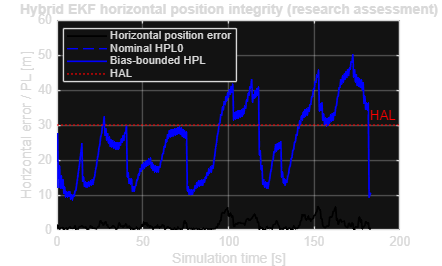

figure('Name','Hybrid EKF - Horizontal Integrity','Color','w');
plot(t,horizontalError,'k','LineWidth',1.3); hold on;
plot(t,HPL0,'b--','LineWidth',1.1);
plot(t,HPL,'b','LineWidth',1.3);
yline(settings.HAL_m,'r:','HAL','LineWidth',1.2);
xlabel('Simulation time [s]'); ylabel('Horizontal error / PL [m]');
legend('Horizontal position error','Nominal HPL0','Bias-bounded HPL','HAL','Location','best');
grid on; title('Hybrid EKF horizontal position integrity (research assessment)');

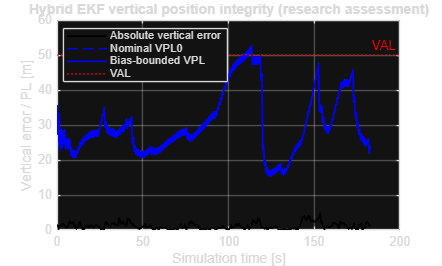


figure('Name','Hybrid EKF - Vertical Integrity','Color','w');
plot(t,verticalError,'k','LineWidth',1.3); hold on;
plot(t,VPL0,'b--','LineWidth',1.1);
plot(t,VPL,'b','LineWidth',1.3);
yline(settings.VAL_m,'r:','VAL','LineWidth',1.2);
xlabel('Simulation time [s]'); ylabel('Vertical error / PL [m]');
legend('Absolute vertical error','Nominal VPL0','Bias-bounded VPL','VAL','Location','best');
grid on; title('Hybrid EKF vertical position integrity (research assessment)');

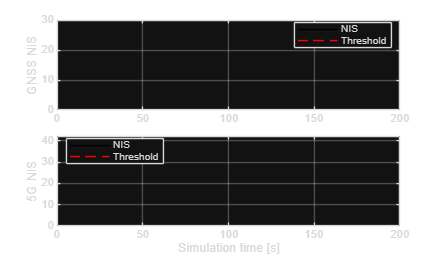


figure('Name','Hybrid EKF - NIS consistency','Color','w');
tiledlayout(2,1,'TileSpacing','compact');
nexttile; plot(t,NISgnss,'k'); hold on; plot(t,NISThreshGnss,'r--');
ylabel('GNSS NIS'); legend('NIS','Threshold','Location','best'); grid on;
nexttile; plot(t,NIS5g,'k'); hold on; plot(t,NISThresh5g,'r--');
ylabel('5G NIS'); xlabel('Simulation time [s]');
legend('NIS','Threshold','Location','best'); grid on;

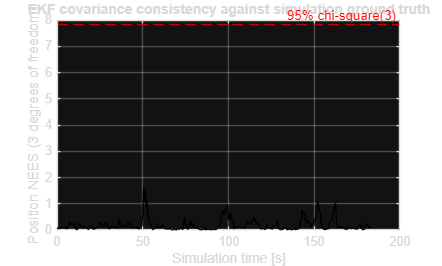


figure('Name','Hybrid EKF - NEES consistency','Color','w');
plot(t,NEESpos,'k'); hold on;
chi3_95=2*gammaincinv(0.95,3/2);
yline(chi3_95,'r--','95% chi-square(3)');
xlabel('Simulation time [s]'); ylabel('Position NEES (3 degrees of freedom)');
grid on; title('EKF covariance consistency against simulation ground truth');

## 7. Save reproducible results and research limitations

The file stores the EKF estimates, ENU position covariance, protection levels, errors, diagnostic test statistics, fault configuration and all settings. The script does NOT use ground truth to correct the filter after initialization.

Before journal publication: (i) verify reference BS and TDOA sign with observation generator, (ii) calibrate GNSS/5G error statistics including LOS/NLOS bias, (iii) tune process-noise spectral density Q, (iv) remove truth-assisted initialization, (v) evaluate fault hypotheses, missed-detection probabilities and time correlation, and (vi) conduct repeated independent Monte Carlo trials.

References: Sánchez-Heredero Martínez, 5G Assisted Precise Positioning in GNSS, MSc thesis, Section 3.2.5. RAIM Fault Detection and Exclusion with Spatial Correlation for Integrity Monitoring, Remote Sensing 15(1), 176 (2023), DOI 10.3390/rs15010176. MATLAB Live Script file specification: MathWorks Live Code File Formats.

results=struct();
results.time_s=t;
results.x_est=x_est;
results.Ppos=Ppos;
results.PposPrior=PposPrior;
results.errorENU=errorENU;
results.horizontalError=horizontalError;
results.verticalError=verticalError;
results.positionError=positionError;
results.HPL0=HPL0; results.VPL0=VPL0;
results.HPL=HPL; results.VPL=VPL;
results.BiasHoriz=BiasHoriz; results.BiasVert=BiasVert;
results.NISgnss=NISgnss; results.NIS5g=NIS5g;
results.NISThreshGnss=NISThreshGnss; results.NISThresh5g=NISThresh5g;
results.NEESpos=NEESpos;
results.GNSSaccepted=GNSSaccepted; results.NRaccepted=NRaccepted;
results.GNSSalarm=GNSSalarm; results.NRalarm=NRalarm;
results.numberGNSS=numberGNSS; results.numberTDOA=numberTDOA;
results.available=available;
results.observedHMI_H=observedHMI_H;
results.observedHMI_V=observedHMI_V;
results.summary=summary;
results.fault=fault;

if exist('ekfSimFile','var') && ~isempty(ekfSimFile)
    [folder,~,~]=fileparts(ekfSimFile);
    if isempty(folder), folder=pwd; end
else
    folder=pwd;
end
ekfIntegrityFile=fullfile(folder,'Hybrid_EKF_Integrity_results.mat');
save(ekfIntegrityFile,'results','settings','-v7.3');
fprintf('Results saved to: %s\n',ekfIntegrityFile);

Results saved to: .\data\estimations\Hybrid_EKF_Integrity_results.mat


## Save latex table

report = Hybrid_EKF_Publication_Export( ...
    results, settings, 'springer_export');